## パス設定

% データリスト読み込み
list = dir(fullfile('C:\Users\daiki\Box\歪・温度計測\2023年度\231112_甲賀出張実験\計測データ\10.csv'));
% dataの階層
pl = fullfile('/Users/daiki_daiku/Library/CloudStorage/Box-Box/Personal/study/Data/2023/231003_ファイバー簡略化\計測データ\');

## gage設定

% g_s = 2108; % 始点位置
g_s = 5996;
g_e = 7795; % 終点位置
start = 0; % 開始時間
fin = 18050/50; % 終了時間
freq = 50; % 周波数
time = linspace(start, fin, fin*freq)'; % 時間軸設定
cut = 3; % 切り取る秒数 
z_row = (start + 6) : (fin - start) * freq + 5;
z_col = g_s : g_e;
% Zmax=80
% Zmin=-3
%testtesttest

## カラーバーの最大値・最小値、軸、データの設定

clearvars Zmax Zmin
for n = 1 : length(list)
    % list(n, 1)に書いてある名前のcsvファイルをreadmatrixで読み込み
    data = readmatrix( [pl list(n).name] );
    if n==1
        Z =data(z_row,z_col) .* (-1);
        Zmax=Z(1, 1);
        Zmin=Z(1, 1);
        Z=filloutliers(Z,"linear");
    else
        Z(:,:,n)=data(z_row,z_col) .* (-1);
        Z(:,:,n)=filloutliers(Z(:,:,n),"linear");
    end
    if n~=6 && n~=8
        if Zmax<max(max(max(Z(:,:,n))))
            Zmax=max(max(max(Z(:,:,n))));
        end
        if Zmin>min(min(min(Z(:,:,n))))
            Zmin=min(min(min(Z(:,:,n))));
        end
    end
end

% ラベル用
x_num_label = linspace(0,1539,5)

x_num_label = 1.0e+03 *

         0    0.3847    0.7695    1.1542    1.5390


x_num_label = round(x_num_label)

x_num_label =            0         385         770        1154        1539


#### 出力テスト

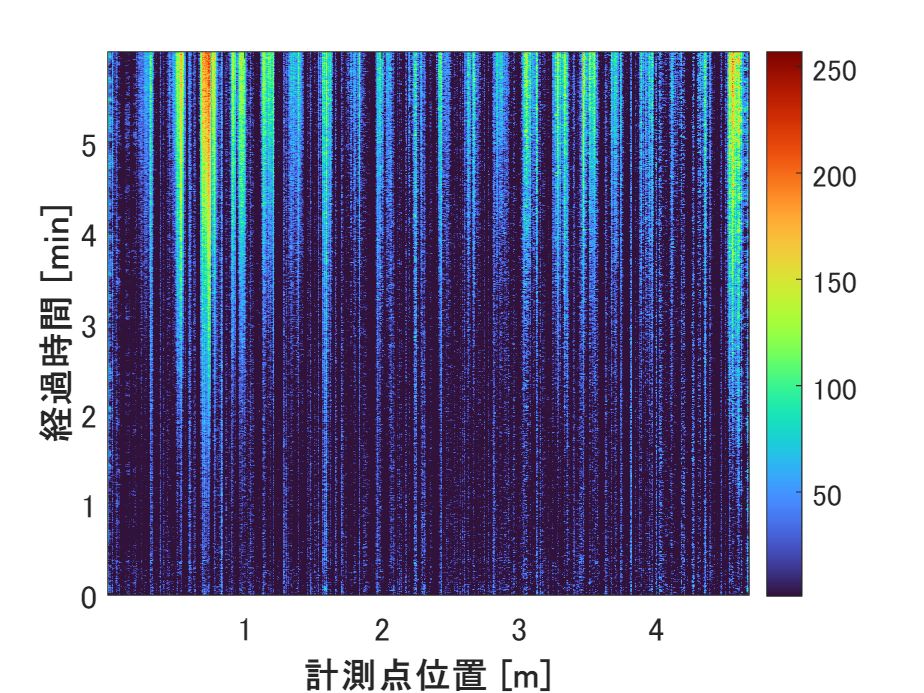

% max(max(max(Z)))
% min(min(min(Z)))
data = readmatrix(fullfile('C:\Users\daiki\Box\歪・温度計測\2023年度\231112_甲賀出張実験\計測データ\10.csv'));
Z =data(z_row,z_col) .* (-1);
Z=filloutliers(Z,"linear");
Zmax = max(max(Z(:,:)));
Zdata = Z(:,:)./Zmax .*256;
Zdata = flipud(Zdata);
image(Zdata);
colormap turbo;
xlabel('計測点位置 [m]','FontSize', 10,'FontWeight', 'bold');
ylabel('経過時間 [min]','FontSize', 10,'FontWeight', 'bold');
yticks([0 3000 6000 9000 12000 15000 18000])
yticklabels({'6','5','4','3','2','1', '0'})
xticks(x_num_label)
xticklabels({'0','1','2','3','4'})
set(gca, 'FontSize', 15);
colorbar

% filloutliers(Z)

t = ones(fix(fin*freq), g_e - g_s + 1 ) .* time; % 縦軸時間
x = ones(fix(fin*freq), g_e - g_s + 1 ) .* data(5, g_s : g_e); % 横軸位置

## 全体画像（contourf）

% % [C,h]=contourf(x, t, Z(:,:,1), LineStyle = "none");
% % colorbar;
% % clim( [Zmin Zmax] );
% % colormap turbo;
% % xlabel('計測点位置 [m]','FontSize', 25, 'FontWeight', 'bold');
% % ylabel('経過時間 [s]', 'FontSize', 25, 'FontWeight', 'bold');
% % text=annotation('textbox', [.9 .05 .5 .5],'String', '[GHz]', 'EdgeColor', 'none', 'FontSize', 20);
% % text.VerticalAlignment = 'bottom';
% % ytickformat('%.1f');
% % xtickformat('%.1f');
% % ax=gca;
% % set(gca, 'FontSize', 20);

% % for n = 1 : length(list)
% %     Num = extractBefore( list(n).name, '.csv' );
% %     h.ZData=Z(:,:,n);
% %     % axis off
% %     filename = append(pl, '分類用画像/raw/' , Num , '.jpg');
% %     exportgraphics(ax, filename, 'Resolution', 300);
% % end

## 全体画像（mesh）

% % s=mesh(x, t, Z(:,:,1));
% % view(2)
% % colorbar;
% % clim( [Zmin Zmax] );
% % xlim([data(5, g_s) data(5, g_e)]);
% % ylim([time(1,1) time(end,1)]);
% % colormap turbo;
% % xlabel('計測点位置 [m]','FontSize', 25, 'FontWeight', 'bold');
% % ylabel('経過時間 [s]', 'FontSize', 25, 'FontWeight', 'bold');
% % text=annotation('textbox', [.9 .05 .5 .5],'String', '[GHz]', 'EdgeColor', 'none', 'FontSize', 20);
% % text.VerticalAlignment = 'bottom';
% % ytickformat('%.1f');
% % xtickformat('%.1f');
% % ax=gca;
% % set(gca, 'FontSize', 20);

% % for n = 1 : length(list)
% %     Num = extractBefore( list(n).name, '.csv' );
% %     s.CData=Z(:,:,n);
% %     % axis off
% %     filename = append(pl, '分類用画像/raw/' , Num , '.jpg');
% %     exportgraphics(ax, filename, 'Resolution', 300);
% % end

% % s = mesh(x,t,Z(:,:,10));
% % xlabel('計測点位置 [m]');
% % ylabel('経過時間 [s]');
% % zlabel('周波数変化*(-1) [GHz]');
% % view(2)

## 全体画像（Image）

% % Zdata = Z(:,:,1)./Zmax .*256;
% % Zdata = flipud(Zdata);
% % s = image(Zdata);
% % colorbar;
% % % clim( [Zmin Zmax] );
% % colormap turbo;
% % xlabel('計測点位置 [mm]','FontSize', 25, 'FontWeight', 'bold');
% % ylabel('経過時間 [s]', 'FontSize', 25, 'FontWeight', 'bold');
% % text=annotation('textbox', [.9 .05 .5 .5],'String', '[GHz]', 'EdgeColor', 'none', 'FontSize', 20);
% % text.VerticalAlignment = 'bottom';
% % yticks([1 500 1000 1500 2000])
% % yticklabels({'20','15','10','5','0'})
% % xticks([1 19 38 58 77 96])
% % xticklabels({'0','50','100','150','200','250'})
% % ax=gca;
% % set(gca, 'FontSize', 20);

for n = 1 : length(list)
    Zdata = Z(:,:,n)./Zmax .*256;
    Zdata = flipud(Zdata);
    Num = extractBefore( list(n).name, '.csv' );
    ax = image(Zdata);
    colormap turbo;
    % axis off
    % xlabel('計測点位置 [m]','FontSize', 35, 'FontWeight', 'bold');
    % ylabel('経過時間 [s]', 'FontSize', 35, 'FontWeight', 'bold');
    xlabel('計測点位置 [m]','FontSize', 30,'FontWeight', 'bold');
    ylabel('経過時間 [s]','FontSize', 30,'FontWeight', 'bold');
    yticks([1 500 1000 1500 2000])
    yticklabels({'20','15','10','5','0'})
    xticks([1 19 38 58 77 96])
    xticklabels({'0','0.05','0.1','0.15','0.2','0.25'})
    set(gca, 'FontSize', 25);
    filename = append(pl, '分類用画像/raw/' , Num , '_ImagePoster.jpg');
    saveas(ax,filename,"jpg")
    % print(filename,f_name,'-r300')
    % imwrite(ax,filename,"jpg")
    % exportgraphics(ax, filename, 'Resolution', 300);
end

## 3秒間隔contourf

% % for n = 1 : length(list)
% %     Num = extractBefore( list(n).name,'.csv' );
% %     for l = 1 : 35
% %         trim1 = (l - 1) * 50 + 1;
% %         trim2 = (l - 1) * 50 + cut * 100 - 1;
% %         z = Z(trim1 : trim2, :,n);
% %         t = ones( size(z) ) .* time(trim1 : trim2, :); % 縦軸時間
% %         x = ones( size(z) ) .* data(5, g_s : g_e); % 横軸位置
% %         contourf(x, t, z, LineStyle = "none"); % グラフ描画
% %         colormap turbo
% %         ax = gcf;
% %         clim( [Zmin Zmax] );
% %         axis off
% %         filename = append(pl, '分類用画像/3秒間隔/', Num, '_', int2str(l), '.jpg');
% %         exportgraphics(ax, filename, 'Resolution', 300);
% %     end
% % end

## 3秒間隔mesh

% % for n = 1 : length(list)
% %     Num = extractBefore( list(n).name,'.csv' );
% %     for l = 1 : 55
% %         trim1 = (l - 1) * 50 + 1;
% %         trim2 = (l - 1) * 50 + cut * 100 - 1;
% %         z = Z(trim1 : trim2, :,n);
% %         t = ones( size(z) ) .* time(trim1 : trim2, :); % 縦軸時間
% %         x = ones( size(z) ) .* data(5, g_s : g_e); % 横軸位置
% %         mesh(x, t, z); % グラフ描画
% %         view(2)
% %         colormap turbo
% %         ax = gcf;
% %         clim( [Zmin Zmax] );
% %         axis off
% %         filename = append(pl, '分類用画像/3秒間隔/', Num, '_', int2str(l), '.jpg');
% %         exportgraphics(ax, filename, 'Resolution', 300);
% %     end
% % end

## 3秒間隔Image

% % for n = 1 : length(list)
% %     Num = extractBefore( list(n).name,'.csv' );
% %     for l = 1 : 35
% %         trim1 = (l - 1) * 50 + 1;
% %         trim2 = (l - 1) * 50 + cut * 100 - 1;
% %         z = flipud(Z(trim1 : trim2, :,n));
% %         t = ones( size(z) ) .* time(trim1 : trim2, :); % 縦軸時間
% %         x = ones( size(z) ) .* data(5, g_s : g_e); % 横軸位置
% %         image(z./Zmax.*256); % グラフ描画
% %         view(2)
% %         colormap turbo
% %         xlabel('計測点位置 [m]','FontSize', 30,'FontWeight', 'bold');
% %         ylabel('経過時間 [s]','FontSize', 30,'FontWeight', 'bold');
% %         yticks([1 50 100 150 200 250 299])
% %         yticklabels({'3.0', '2.5', '2.0','1.5','1.0','0.5','0'})
% %         xticks([1 19 38 58 77 96])
% %         xticklabels({'0','0.05','0.1','0.15','0.2','0.25'})
% %         set(gca, 'FontSize', 25);
% %         ax = gcf;
% %         clim( [Zmin Zmax] );
% %         % axis off
% %         filename = append(pl, '分類用画像/3秒間隔_imageforposter/', Num, '_', int2str(l), '.jpg');
% %         exportgraphics(ax, filename, 'Resolution', 300);
% %     end
% % end